%calculate the average probability

R = [-0.0115,  0.0095,  0; ...
         0.0115, -0.0180,  0.0440; ...
         0.0000,  0.0085, -0.0440];

t_long = 5000;
p_avg = expm(R*t_long) * [1;0;0];
error = R* p_avg

error =    1.0e-18 *

   -0.2972
    0.0194
    0.8480


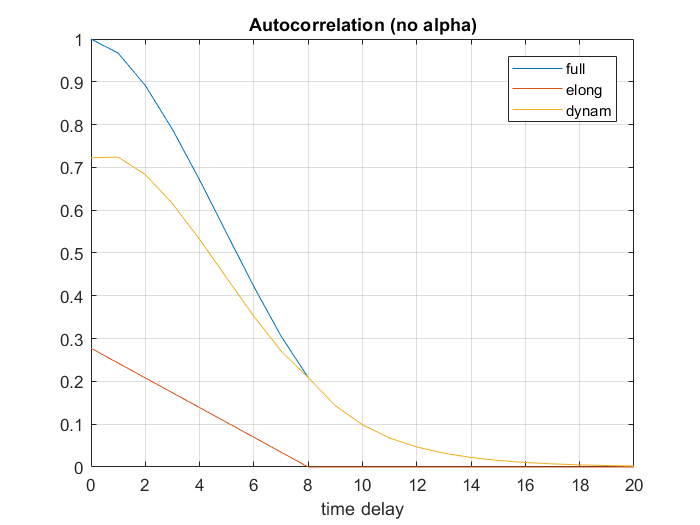

%calculates the expected autocorrelation

elong_time = 8;
deltaT = 20;
r_emission = [3,65,120];
max_delay = 20;
K = 3;

sol = zeros(1,max_delay+1);
elong_cor = zeros(1,max_delay + 1);
dynam_cor = zeros(1,max_delay + 1);

%calculates elongation term

elong_coeff = sum(p_avg' .* r_emission*deltaT .* (1 + r_emission*deltaT));
for i = 1:elong_time
    sol(i) = sol(i) + (elong_time - i + 1) * elong_coeff;
    elong_cor(i) = sol(i) - sum(p_avg' .* r_emission * deltaT)^2 * (elong_time - i + 1);
end

%calculates dynamics correlation term

expectations = zeros(1,max_delay + elong_time - 1);
for i = 1:(max_delay + elong_time - 1)
    for k = 1:K
        p_delay = zeros(K,1);
        p_delay(k) = 1;
        p_delay = expm(R*deltaT*i)* p_delay;
        expectations(i) = expectations(i) + sum(p_delay' .* r_emission*deltaT) ...
            * r_emission(k) * deltaT * p_avg(k);
    end
end

% adds dynamics correlation to terms where elong_time > time_delay

for i = 1:elong_time
    delay = i - 1;
    if delay >= 1
        for j = 1:delay
            sol(i) = sol(i) + (elong_time - delay + j)*expectations(j);
            dynam_cor(i) = dynam_cor(i) + (elong_time - delay + j)*expectations(j);
        end
    end
    for j = 1:(elong_time - delay)
        sol(i) = sol(i) + (elong_time - delay - j)*expectations(j);
        dynam_cor(i) = dynam_cor(i) + (elong_time - delay - j)*expectations(j);
    end
    for j = (delay + 1):(elong_time + delay)
        sol(i) = sol(i) + (elong_time + delay - j)*expectations(j);
        dynam_cor(i) = dynam_cor(i) + (elong_time + delay - j)*expectations(j);
    end
    dynam_cor(i) = dynam_cor(i) - sum(p_avg' .* r_emission * deltaT)^2 ...
        * (elong_time^2 - elong_time + i - 1);
end

% adds dynamics correlation to terms where elong_time <= time_delay

for i = elong_time:max_delay
    delay = i;
    for j = (1 - elong_time + delay):delay
        sol(delay + 1) = sol(delay+1) + (j + elong_time - delay)*expectations(j);
    end
    for j = (delay+1):(elong_time + delay-1)
        sol(delay+1) = sol(delay+1) + (elong_time + delay - j)*expectations(j);
    end
    dynam_cor(delay + 1) = sol(delay+1) - ...
        (elong_time * sum(p_avg' .* r_emission * deltaT))^2;
end

%calculates the mean and subtracts the mean squared from every term

mu = elong_time * sum(p_avg' .* r_emission * deltaT);
sol = sol - mu*mu;
elong_cor = elong_cor / sol(1);
dynam_cor = dynam_cor / sol(1);
sol = sol / sol(1);

%plots autocorrelation

figure()
plot(0:max_delay, sol);
hold on
plot(0:max_delay, elong_cor);
hold on
plot(0:max_delay, dynam_cor);
title("Autocorrelation (no alpha)");
legend('full','elong','dynam');
xlabel("time delay");
grid on

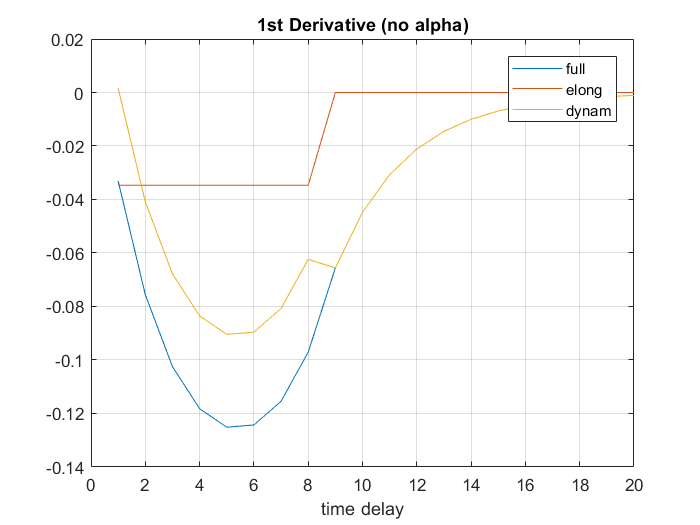


%plots first derivative of autocorrelation

deriv_1st = sol(2:max_delay + 1) - sol(1:max_delay);
deriv_1st_elong = elong_cor(2:max_delay + 1) - elong_cor(1:max_delay);
deriv_1st_dynam = dynam_cor(2:max_delay + 1) - dynam_cor(1:max_delay);

figure()
plot(1:max_delay, deriv_1st);
hold on
plot(1:max_delay, deriv_1st_elong);
hold on
plot(1:max_delay, deriv_1st_dynam);
grid on
title("1st Derivative (no alpha)");
legend('full','elong','dynam');
xlabel("time delay");

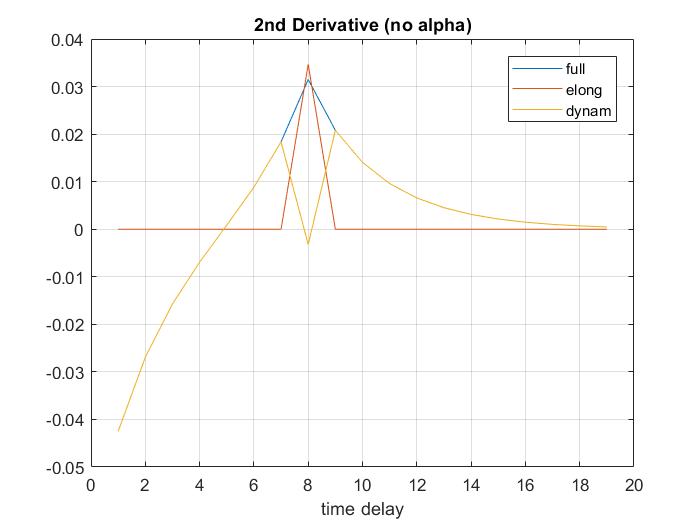


%plots 2nd derivative

deriv_2nd = deriv_1st(2:end) - deriv_1st(1:end - 1);
deriv_2nd_elong = deriv_1st_elong(2:end) - deriv_1st_elong(1:end-1);
deriv_2nd_dynam = deriv_1st_dynam(2:end) - deriv_1st_dynam(1:end-1);

figure()
plot(1:max_delay-1, deriv_2nd);
hold on
plot(1:max_delay-1, deriv_2nd_elong);
hold on
plot(1:max_delay-1, deriv_2nd_dynam);
grid on
title("2nd Derivative (no alpha)");
legend('full','elong','dynam');
xlabel("time delay");

Below is the code for generating the expected plots for the autocorrelation when the rise time is factored in

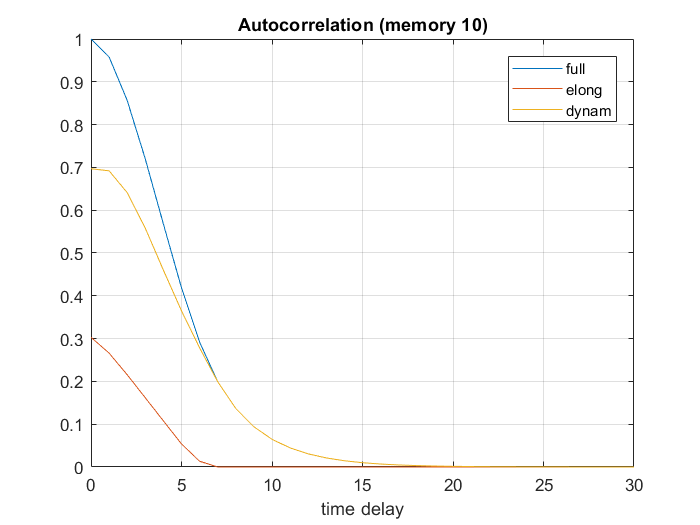

%calculates the expected autocorrelation with the rise time taken into account

%sets the variables
R = [-0.0115,  0.0095,  0.0000; ...
         0.0115, -0.0180,  0.0440; ...
         0.0000,  0.0085, -0.0440];

t_long = 5000;
p_avg = expm(R*t_long) * [1;0;0];

elong_time = 7;
deltaT = 20;
r_emission = [1,65,130];
max_delay = 30;
K = 3;
rise_time = 2;
rt = rise_time; % for convenience and readability
plot_others = true;

%sets up arrays for the solution
sol = zeros(1,max_delay+1);
elong_cor = zeros(1,max_delay + 1);
dynam_cor = zeros(1,max_delay + 1);

%calculates the mean of individual time steps
mu = sum(p_avg' .* r_emission * deltaT);

%calculates and adds the elongation correlation term

elong_coeff = sum(p_avg' .* r_emission*deltaT .* (1 + r_emission*deltaT));
for i = 1:elong_time
    delay = i-1;
    exp_coeff = 0;
    for j = 1:(elong_time - delay)
        exp_coeff = exp_coeff + alpha(elong_time - j,rt)*alpha(elong_time - j - delay,rt);
    end
    sol(i) = exp_coeff * (elong_coeff - mu*mu);
    elong_cor(i) = sol(i);
end

%calculates expectations for the dynamics correlation terms

expectations = zeros(1,max_delay + elong_time - 1);
for i = 1:(max_delay + elong_time - 1)
    for k = 1:K
        p_delay = zeros(K,1);
        p_delay(k) = 1;
        p_delay = expm(R*deltaT*i)* p_delay;
        expectations(i) = expectations(i) + sum(p_delay' .* r_emission*deltaT) ...
            * r_emission(k) * deltaT * p_avg(k);
    end
end

%calculates and adds the dynamics correlation terms

for i = 1:(max_delay+1)
    dynam_term = 0;
    delay = i - 1;
    
    if delay > 0
        for j = 1:delay
            exp_coeff = 0;
            for k = 1:(elong_time - delay + j)
                exp_coeff = exp_coeff + alpha(elong_time - k,rt)*alpha(elong_time - k - (delay - j),rt);
            end
            dynam_term = dynam_term + exp_coeff * (expectations(j) - mu*mu);
        end
    end

    if delay < elong_time
        for j = 1:(elong_time - delay)
            exp_coeff = 0;
            for k = 1:(elong_time - delay - j)
                exp_coeff = exp_coeff + alpha(elong_time - k,rt)*alpha(elong_time - k - delay - j,rt);
            end
            dynam_term = dynam_term + exp_coeff * (expectations(j) - mu*mu);
        end
    end

    for j = (delay + 1):(elong_time + delay-1)
        exp_coeff = 0;
        for k = 1:(elong_time + delay - j)
            exp_coeff = exp_coeff + alpha(elong_time - k,rt)*alpha(elong_time - k - (j - delay),rt);
        end
        dynam_term = dynam_term + exp_coeff * (expectations(j) - mu*mu);
    end

    sol(i) = sol(i) + dynam_term;
    dynam_cor(i) = dynam_cor(i) + dynam_term;
end

%subtracts the mean squared from every term

elong_cor = elong_cor / sol(1);
dynam_cor = dynam_cor / sol(1);
sol = sol / sol(1);


%plots autocorrelation

figure()
plot(0:max_delay, sol);
if plot_others
    hold on
    plot(0:max_delay, elong_cor);
    hold on
    plot(0:max_delay, dynam_cor);
end
title("Autocorrelation (memory 10)");
legend('full','elong','dynam');
xlabel("time delay");
grid on

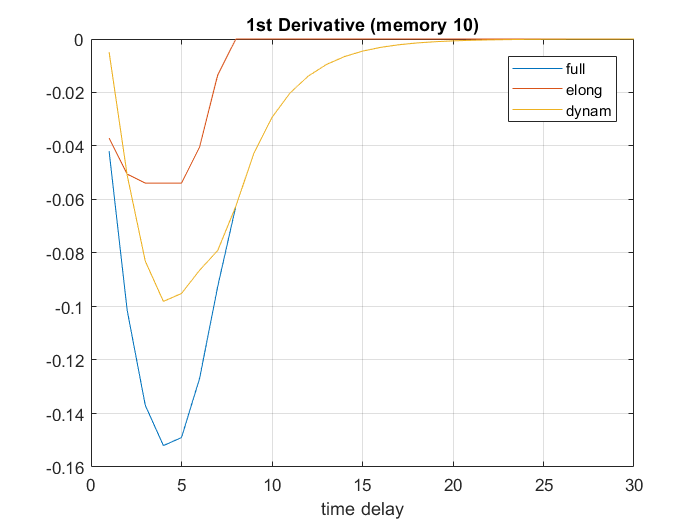


%plots first derivative of autocorrelation

deriv_1st = sol(2:max_delay + 1) - sol(1:max_delay);
deriv_1st_elong = elong_cor(2:max_delay + 1) - elong_cor(1:max_delay);
deriv_1st_dynam = dynam_cor(2:max_delay + 1) - dynam_cor(1:max_delay);

figure()
plot(1:max_delay, deriv_1st);
if plot_others
    hold on
    plot(1:max_delay, deriv_1st_elong);
    hold on
    plot(1:max_delay, deriv_1st_dynam);
end
grid on
title("1st Derivative (memory 10)");
legend('full','elong','dynam');
xlabel("time delay");

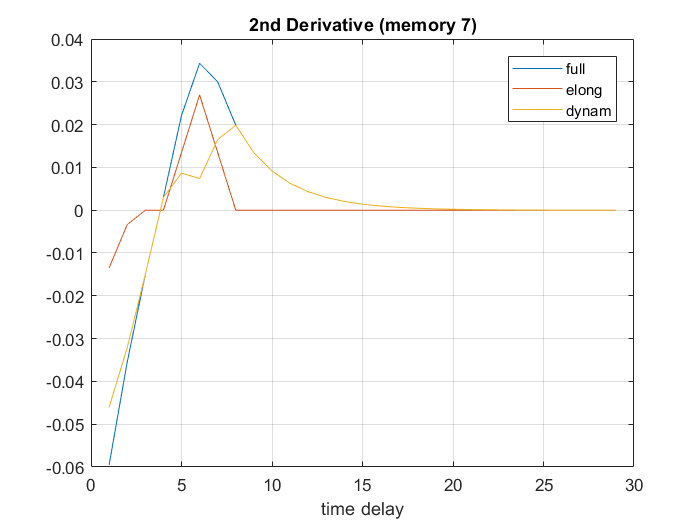


%plots 2nd derivative

deriv_2nd = deriv_1st(2:end) - deriv_1st(1:end - 1);
deriv_2nd_elong = deriv_1st_elong(2:end) - deriv_1st_elong(1:end-1);
deriv_2nd_dynam = deriv_1st_dynam(2:end) - deriv_1st_dynam(1:end-1);

figure()
plot(1:max_delay-1, deriv_2nd);
if plot_others
    hold on
    plot(1:max_delay-1, deriv_2nd_elong);
    hold on
    plot(1:max_delay-1, deriv_2nd_dynam);
end
grid on
title("2nd Derivative (memory 7)");
legend('full','elong','dynam');
xlabel("time delay");